# Controlling the separator level

clear

## Model linarisation

format long
% The internal states are ordered:
% P2, X2, P100 lag, L2, F200 lag, F2 lag
x_op = [50.5, 25, 194.7, 1, 208, 2];

% The inputs are orderes:
% F1, X1, T1, F2, P100, F3, F200, T200
u_op = [10, 5, 40, 2, 194.7, 50, 208, 25];

[A, B, C, D] = linmod('plant', x_op, u_op);

% Also store it in a linear system model

% Get tf enumerator and denominator coefficients from exciting F2
% (input no. 4)
[b, a] = ss2tf(A, B, C, D, 4);
% Pick out the tf coefficient in b to L2
% (output no. 4)
b = b(4, :);

% Create tf from the calculated coefficients
% Also create SISO model just F2 to L2
tf_F2_L2 = tf(b, a);
sys = ss(tf_F2_L2);

## Controller design

#### Trial and error 50% overshoot controller    

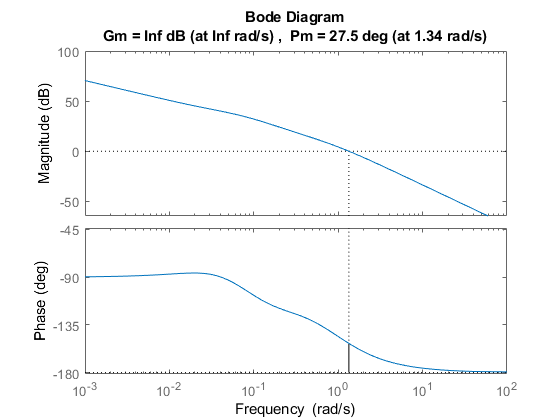

% 50% overshoot controller
margin(sys * -1 * 50)

#### 45° phase margin P controller

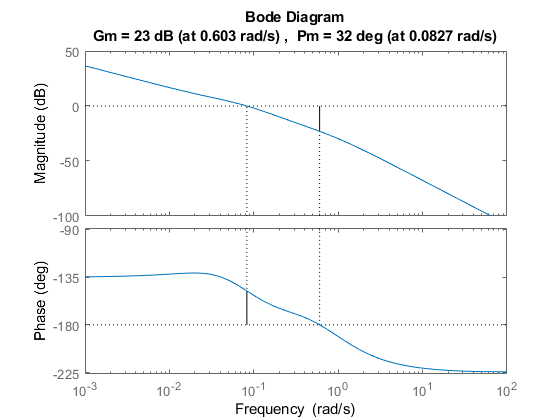

% For finding 45° phase margin gain
margin(tf_F2_L2 * -1 * exp(-pi/4 * 1i))

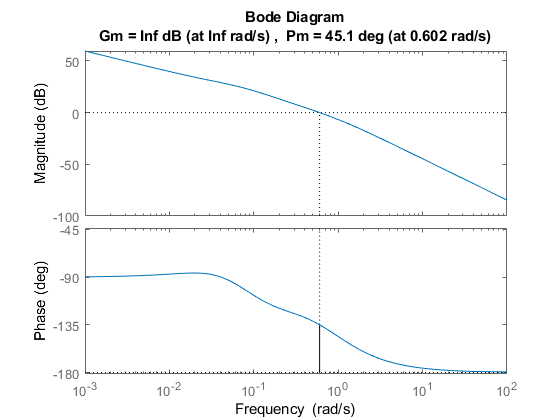

% 45° phase margin controller
margin(sys * -1 * 10^(23/20))

#### 40° phase margin PI controller

% PI controller
Kp = -1 * 10^(23/20);
Ti = -1/(tan(-5 * pi/180) * 0.602);
tf_controller = tf([Kp*Ti, Kp], [Ti, 0])


tf_controller =
 
  -268.2 s - 14.13
  ----------------
      18.99 s
 
Continuous-time transfer function.



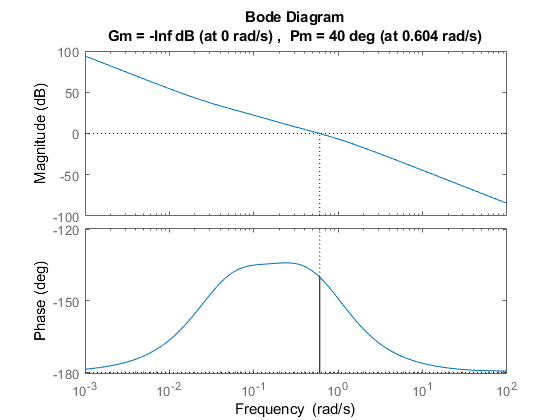


margin(sys * tf_controller)

% Calculating P, I for simulink PID block
P = Kp;
I = Kp/Ti;

fprintf('The PI controller needs Ti = %0.4e', Ti)

The PI controller needs Ti = 1.8987e+01

fprintf('For implementing in the PID block P = %0.4e; I = %0.4e', P, I)

For implementing in the PID block P = -1.4125e+01; I = -7.4396e-01

#### More accurate P, I calculation using trial and error

% Calculating P, I for simulink PID block more precisely

[Gm Pm] = margin(sys*P), P

Gm =    Inf


Pm =   45.057479676163588


P =  -14.125375446227540


Kp = -14.184747876062640;
[Gm,Pm,Wcg,Wcp] = margin(sys*Kp)

Gm =    Inf


Pm =     45


Wcg =    Inf


Wcp =    0.603764307096840


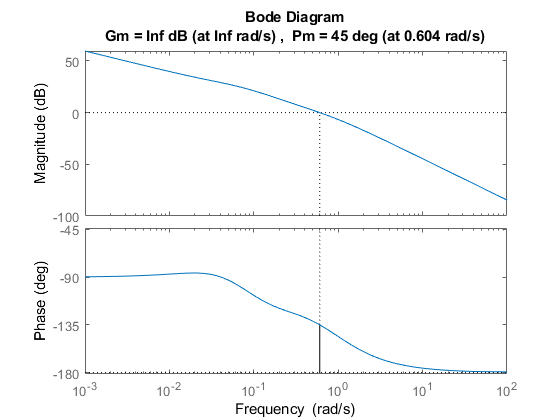

margin(sys*Kp)

P = Kp;
Ti = 1/(tan(5 * pi/180) * Wcp);
I = Kp/Ti;

fprintf('The PI controller needs Ti = %0.4e', Ti);

The PI controller needs Ti = 1.8931e+01

fprintf('For implementing in the PID block P = %0.4e; I = %0.4e', P, I)

For implementing in the PID block P = -1.4185e+01; I = -7.4927e-01

Ti

Ti =   18.931315032056109


I

I =   -0.749274303028808


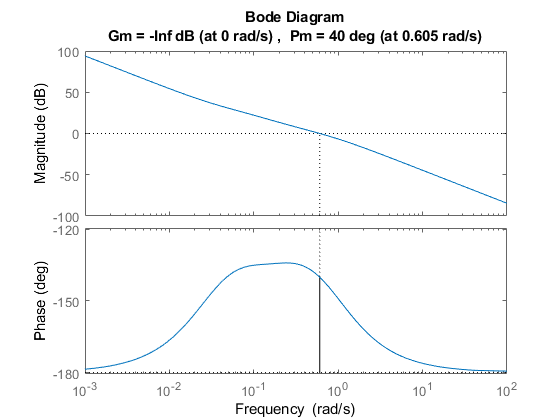

margin(sys * tf([Kp*Ti, Kp], [Ti, 0]))

[Gm,Pm,Wcg,Wcp] = margin(sys * tf([Kp*Ti, Kp], [Ti, 0]))

Gm =      0


Pm =   39.960946071192936


Wcg =      0


Wcp =    0.605365917585549


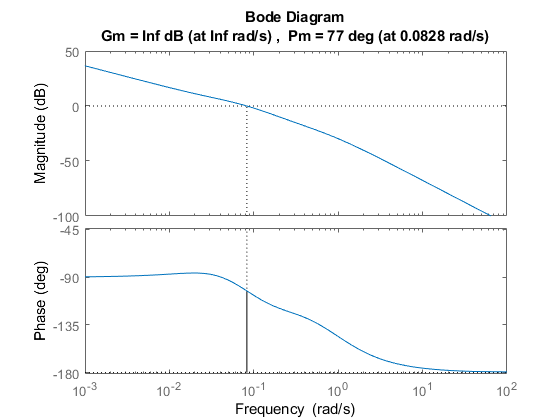

margin(-sys)

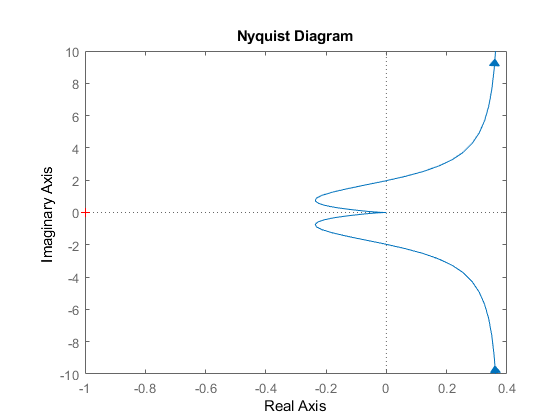

nyquist(-sys)    